## Load 3D Pyramid Data

addpath('E:/Projects/Pyramid_model/Matlab_code/function');

path_table = "E:/Projects/Pyramid_model/tables/";
path_fig = "E:/Projects/Pyramid_model/figures/";

max_intensity = readtable(path_table+"max_intensity.csv");
pnts = readtable(path_table+"sim_pnts_cluster.csv");

warning('off','all')

% ------- load the pyramids of clustered points ------------
array3D_i = load(path_table + "array3D_intensity.mat");
array3D_i = array3D_i.vect;
array3D_i = flip(array3D_i,1);

array3D_res = load(path_table + "array3D_residual.mat");
array3D_res = array3D_res.vect;
array3D_res = flip(array3D_res,1);

s = size(array3D_i);
z_scale = 0.75;

## Create Pyramid and Rescale data

array3D_p = NaN(s(1),s(2),s(3)); % min-max scaling by layer
array3D_pct = NaN(s(1),s(2),s(3)); % min-max scaling by layer

for i = 1: s(3)
%for i = 100: 101

    edge = i;
    
    % ------- get only the volume in the pyramid --------
    layer = array3D_i((1+edge):(s(1)-edge),(1+edge):(s(2)-edge),i);
    %layer = array3D_i(:,:,i);
    
    % ------ convert the values in each layers into percentile scores------
    minimum = min(min(layer));
    maximum = max(max(layer));
    result = (layer - minimum)/(maximum-minimum);
    %result = layer; 
    flat_layer = reshape(layer,1,[]);
    [sorted,idx]=sort(flat_layer,'Ascend');
    sorted_flat_layer=zeros(size(sorted));
    sorted_flat_layer(idx)=1:length(sorted);
    sorted_flat_layer = sorted_flat_layer/length(flat_layer);
    result_pct=reshape(sorted_flat_layer,size(layer));
    
    array3D_p((1+edge):(s(1)-edge),(1+edge):(s(2)-edge),i) = result;
    %array3D_p(:,:,i) = result;
    array3D_pct((1+edge):(s(1)-edge),(1+edge):(s(2)-edge),i) = result_pct;
    
end

lv1=array3D_pct(:,:,1);
lv1(lv1<1)=0;
array3D_pct(:,:,1) = lv1;

## Plot the maximum intensity points

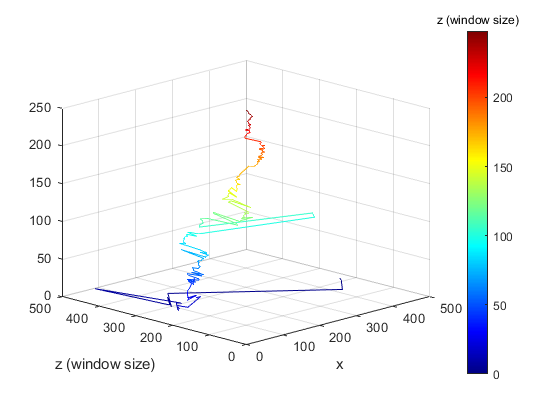

cla;
hold off;
% ax1 = subplot(3,1,1);

x = max_intensity.x;
y = 500-max_intensity.y;
z = max_intensity.z; 

%c = sub_lines.z(1).*int16(ones(height(z),1));
%figure;
%h1 = axes;
plot3(x,y,z);
patch([x.' nan],[y.' nan],[z.' nan],[z.' nan],'FaceColor','none','EdgeColor','interp');
colormap('jet');
colorbar
view(3)
%set(h1,'XDir','reverse');
%set(h1,'YDir','reverse');
%disp(min(sub_lines.z));
%patch(x, y, z, c,'EdgeColor','interp','FaceColor','none');
xlim([0 500]);
ylim([0 500]);
pbaspect([1 1 z_scale]);
grid on;

% title('Moving trajectory of densest quadrat centroid in the PM');
xlabel('x');
ylabel('y');
ylabel('z (window size)');
hcb=colorbar;
hcb.Title.String = "z (window size)";
view(-45,15);
exportgraphics(gcf,strcat(path_fig,'45-15','.png'),'Resolution',300);

## Display Density Slices

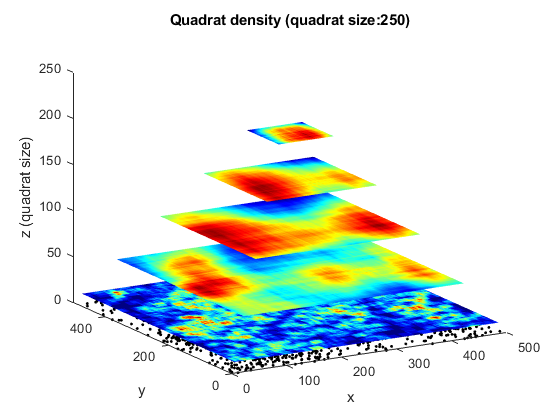

% slice_v =27
cla;
%for slice_v = [2,5,10,20,40,60,80,100,120,140,160,180,200,220,240,260]
for slice_v = [10,50,100,150,200,250]
    scatter3(pnts.x,pnts.y,pnts.y*0,5,'filled','MarkerFaceColor','black');
    hold on;
    
    sl = slice(array3D_p,[],[],slice_v,'EdgeColor','none');
    sl.EdgeColor = 'none';
    iso_value_s=num2str(slice_v);
        
    % Add the base map
    %base=array3D_p(:,:,1);
    
    view(-30,15);
    xlabel('x')
    ylabel('y')
    zlabel('z (quadrat size)')
    
    grid off
    xlim([0 500]);
    ylim([0 500]);
    zlim([0 250]);
    pbaspect([1 1 z_scale]);
    title(strcat('Quadrat density (quadrat size: ',num2str(slice_v),')'));
    drawnow;
    hold on;
    exportgraphics(gcf,strcat(path_fig,'intensity_slice',num2str(slice_v),'.png'),'Resolution',300);
end
 exportgraphics(gcf,strcat(path_fig,'intensity_slice_all2.png'),'Resolution',300);

## Plot the maximum intensity points with quadrat layers

cla;
hold off;
% ax1 = subplot(3,1,1);

x = max_intensity.x;
y = 500-max_intensity.y;
z = max_intensity.z; 

plot3(x,y,z);
colormap('jet');
p = patch([x.' nan],[y.' nan],[z.' nan],[z.' nan],'FaceColor','none','EdgeColor','interp','LineWidth',1.5);
view(3);
%set(h1,'XDir','reverse');
%set(h1,'YDir','reverse');
%disp(min(sub_lines.z));
%patch(x, y, z, c,'EdgeColor','interp','FaceColor','none');

hold on;
%for slice_v = [2,5,10,20,40,60,80,100,120,140,160,180,200,220,240,260]
for slice_v = [10,50,100,150,200,250]
    scatter3(pnts.x,pnts.y,pnts.y*0,5,'filled','MarkerFaceColor','black');
    hold on;
    
    sl = slice(array3D_p,[],[],slice_v,'EdgeColor','none');
    sl.EdgeColor = 'none';
    iso_value_s=num2str(slice_v);
        
    % Add the base map
    %base=array3D_p(:,:,1);
    
    view(-30,15);
    xlabel('x')
    ylabel('y')
    zlabel('z (quadrat size)')
    
    grid off
    xlim([0 500]);
    ylim([0 500]);
    zlim([0 250]);
    pbaspect([1 1 z_scale]);
    title(strcat('Quadrat density (quadrat size: ',num2str(slice_v),')'));
    drawnow;
    hold on;
end
exportgraphics(gcf,strcat(path_fig,'quadrat_density_and_peak.png'),'Resolution',300);

## Display base points

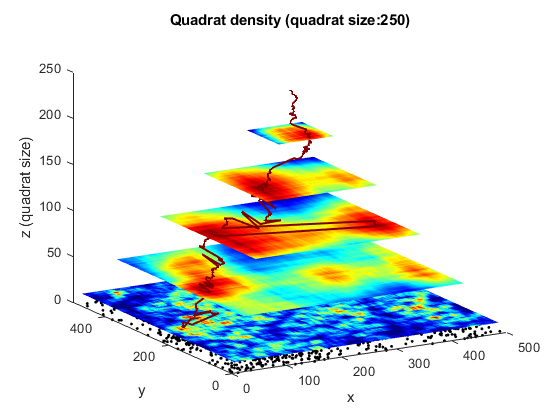

hold off;

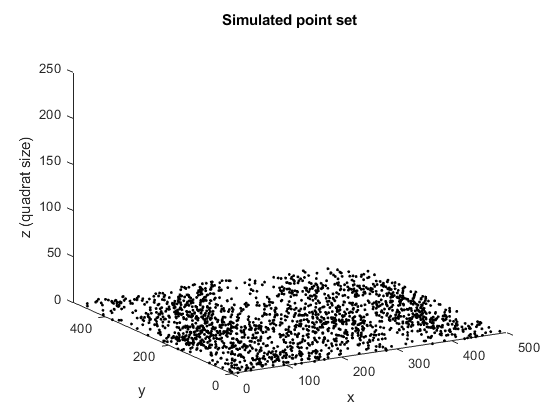

cla;
scatter3(pnts.x,pnts.y,pnts.y*0,5,'filled','MarkerFaceColor','black');

view(-30,15);
xlabel('x')
ylabel('y')
zlabel('z (quadrat size)')

grid off
xlim([0 500]);
ylim([0 500]);
zlim([0 250]);
pbaspect([1 1 z_scale]);
title('Simulated point set');
drawnow;
hold on;
exportgraphics(gcf,strcat(path_fig,'basepoints2.png'),'Resolution',300);

## Plot 3D Pyramid 

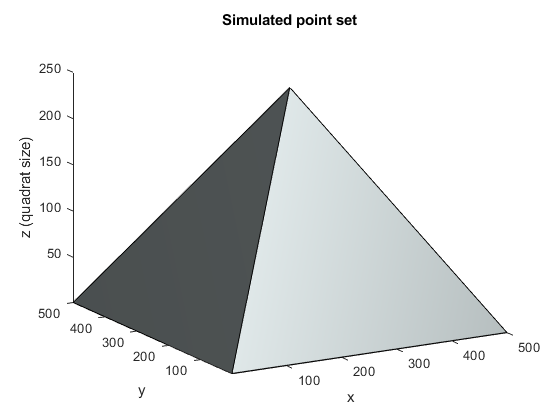

%  ----- Add the pyramid semi-transparent framework -----
cla;
hold off;
dim=size(array3D_i);
dim_x=dim(1);
dim_y=dim(2);
dim_z=dim(3);
a_value = 1;

pbaspect([1 1 z_scale]);
view(3); 
axis tight
c = [153 163 164]/256;
X=[dim_x/2,1,1];
Y=[dim_y/2,1,dim_x];
Z=[dim_z,1,1];
p=patch(X,Y,Z,c);
p.FaceAlpha=a_value;

X=[dim_x/2,1,dim_x];
Y=[dim_y/2,1,1];
Z=[dim_z,1,1];
p=patch(X,Y,Z,c);
p.FaceAlpha=a_value;

X=[dim_x/2,1,dim_x];
Y=[dim_y/2,dim_x,dim_y];
Z=[dim_z,1,1];
p=patch(X,Y,Z,c);
p.FaceAlpha=a_value;

X=[dim_x/2,dim_x,dim_x];
Y=[dim_y/2,dim_y,1];
Z=[dim_z,1,1];
p=patch(X,Y,Z,c);
p.FaceAlpha=a_value;

p.FaceColor = c;
p.EdgeColor = 'none';
camlight 
lighting gouraud;
xlabel('x')
ylabel('y')
zlabel('z (quadrat size)')
view(-30,15);
 exportgraphics(gcf,strcat(path_fig,'Pyramid_frame','.png'),'Resolution',300);

## Plot 3D Cube

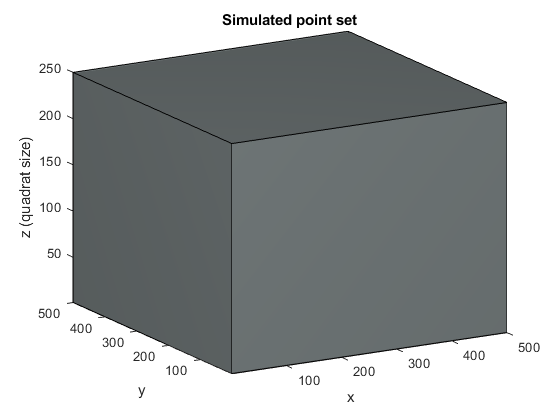

%  ----- Add the pyramid semi-transparent framework -----
cla;
hold off;
dim=size(array3D_i);
dim_x=dim(1);
dim_y=dim(2);
dim_z=dim(3);
a_value = 1;

pbaspect([1 1 z_scale]);
view(3); 
axis tight
c = [153 163 164]/256;
X=[1,dim_x,dim_x,1];
Y=[1,1,dim_y,dim_y];
Z=[1,1,1,1];
p=patch(X,Y,Z,c);
p.FaceAlpha=a_value;

X=[dim_x,dim_x,dim_x,dim_x];
Y=[1,1,dim_y,dim_y];
Z=[1,dim_z,dim_z,1];
p=patch(X,Y,Z,c);
p.FaceAlpha=a_value;

X=[1,dim_x,dim_x,1];
Y=[dim_y,dim_y,dim_y,dim_y];
Z=[1,1,dim_z,dim_z];
p=patch(X,Y,Z,c);
p.FaceAlpha=a_value;

X=[1,1,1,1];
Y=[1,1,dim_y,dim_y];
Z=[1,dim_z,dim_z,1];
p=patch(X,Y,Z,c);
p.FaceAlpha=a_value;

X=[1,dim_x,dim_x,1];
Y=[1,1,1,1];
Z=[dim_z,dim_z,dim_z,dim_z];
p=patch(X,Y,Z,c);
p.FaceAlpha=a_value;

X=[1,dim_x,dim_x,1];
Y=[1,1,dim_y,dim_y];
Z=[dim_z,dim_z,dim_z,dim_z];
p=patch(X,Y,Z,c);
p.FaceAlpha=a_value;

X=[1,dim_x,dim_x,1];
Y=[1,1,1,1];
Z=[1,1,dim_z,dim_z];
p=patch(X,Y,Z,c);
p.FaceAlpha=a_value;

p.FaceColor = c;
p.EdgeColor = 'none';
camlight('headlight');
lighting gouraud;
xlabel('x')
ylabel('y')
zlabel('z (quadrat size)')
view(-30,15);
 exportgraphics(gcf,strcat(path_fig,'cub_frame','.png'),'Resolution',300);

## Plot isosurface at one level

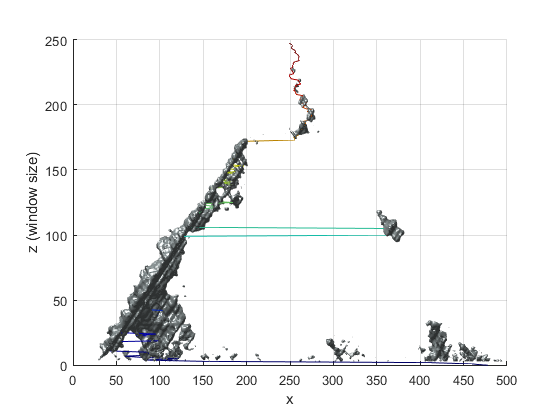

cla;
hold off;
x = max_intensity.x;
y = 500-max_intensity.y;
z = max_intensity.z; 

plot3(x,y,z);
colormap('jet');
p = patch([x.' nan],[y.' nan],[z.' nan],[z.' nan],'FaceColor','none','EdgeColor','interp');
view(3)

xlim([0 500]);
ylim([0 500]);
pbaspect([1 1 0.5]);

hold on;

% -------------------- Plot high density voxels ---------------------------

isovalue=0.99;
p=patch(isosurface(smooth3(array3D_pct,'box',3),isovalue:1));

p.FaceColor = '#99A3A4';
p.EdgeColor = 'none';
camlight('headlight'); 
lighting gouraud;
xlim([0 s(1)]);
ylim([0 s(2)]);
zlim([0 s(3)]);
xlabel('x'); 
ylabel('y');
zlabel('z (window size)');
pbaspect([1 1 z_scale]);
grid on;
view(-45,15);
exportgraphics(gcf,strcat(path_fig,'Intensity_',num2str(isovalue),'pct_45-15_L.png'),'Resolution',300);

## Plot isosurface with quadrat density slices

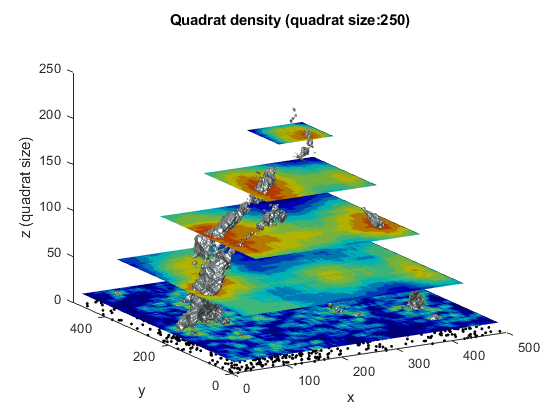

cla;

hold off;
view(3)


% -------------------- Plot high density voxels ---------------------------

isovalue=0.99;
p=patch(isosurface(smooth3(array3D_pct,'box',3),isovalue:1));

p.FaceColor = '#99A3A4';
p.EdgeColor = 'none';
camlight('headlight'); 
lighting gouraud;
xlim([0 s(1)]);
ylim([0 s(2)]);
zlim([0 s(3)]);
xlabel('x'); 
ylabel('y');
zlabel('z (window size)');
pbaspect([1 1 z_scale]);
grid on;
view(-45,15);

% ---------------- Plot slices of quadrat density -------------------------
hold on;

for slice_v = [10,50,100,150,200,250]
    scatter3(pnts.x,pnts.y,pnts.y*0,5,'filled','MarkerFaceColor','black');
    hold on;
    
    sl = slice(array3D_p,[],[],slice_v,'EdgeColor','none');
    sl.EdgeColor = 'none';
    iso_value_s=num2str(slice_v);
        
    % Add the base map
    %base=array3D_p(:,:,1);
    
    view(-30,15);
    xlabel('x')
    ylabel('y')
    zlabel('z (quadrat size)')
    
    grid off
    xlim([0 500]);
    ylim([0 500]);
    zlim([0 250]);
    pbaspect([1 1 z_scale]);
    title(strcat('Quadrat density (quadrat size: ',num2str(slice_v),')'));
    drawnow;
    hold on;
end

exportgraphics(gcf,strcat(path_fig,'voxels_with_slices.png'),'Resolution',300);

## Plot isosurface array3D_p

cla;
%for isovalue = [0.0005,0.001,0.002,0.004,0.005,0.01,0.02]
isovalue=0.0005;
disp(strcat('ISOVALUE: ', num2str(isovalue)));

ISOVALUE:0.0005


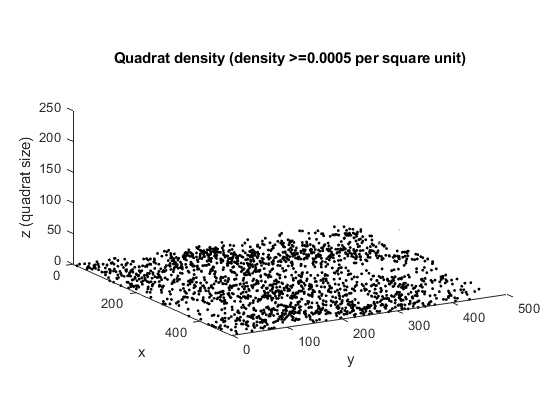

scatter3(pnts.x,pnts.y,pnts.y*0,5,'filled','MarkerFaceColor','black');
hold on;

colormap(jet(10))

p=patch(isosurface(smooth3(array3D_pct,'box',7),isovalue:1));

p.FaceColor = '#99A3A4';
p.EdgeColor = 'none';
camlight 
lighting gouraud;
xlim([0 s(1)]);
ylim([0 s(2)]);
zlim([0 s(3)]);
xlabel('x'); 
ylabel('y');
zlabel('z (quadrat size)');
pbaspect([1 1 0.5]);
view(60,15);
title(strcat('Quadrat density (density >= ',num2str(isovalue),' per square unit)'));

drawnow;
hold off;

exportgraphics(gcf,strcat(path_fig,'all_intensity',num2str(isovalue),'.png'),'Resolution',300);

%saveas(gcf,strcat(path_fig,num2str(isovalue),'.png'))
%end

## Test FastPeakFind

img_path = 'E:/Projects/Pyramid_model/Matlab_code/figures/';
%imwrite(array3D_pct(:,:,100),strcat(img_path,'myImage.jpeg'),'JPEG');
z = 5;
[cent, varargout]=FastPeakFind(array3D_pct(:,:,z), 0);
s_cent = size(cent);
coords = zeros(s_cent(1)/2,2);
for i = 1:s_cent(1)/2
    coords(i,1)=cent(2*i-1);
    coords(i,2)=cent(2*i);
end

coords = array2table(coords,'VariableNames',{'x','y'})
imagesc(array3D_pct(:,:,z));
hold on;
scatter(coords.x,coords.y,10,'MarkerFaceColor','black',"MarkerEdgeColor","none");
hold off;
sl = slice(array3D_p,[],[],z,'EdgeColor','none');
sl.EdgeColor = 'none';
hold on;
scatter3(coords.x,coords.y,coords.y*0+z,5,'filled','MarkerFaceColor','blue');
hold off;

## Compute peaks in all levels

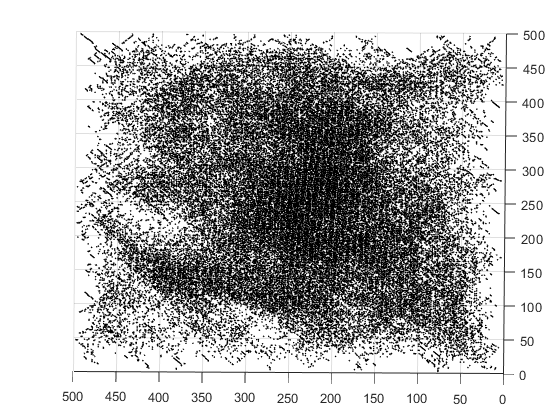

% Create empty table to store peaks in all levels
variable_names_types = [["id", "int16"];["x", "int16"]; ["y", "int16"]; ["z", "int16"]];
% Make table using fieldnames & value types from above
all_coords = table('Size',[0,size(variable_names_types,1)],... 
	'VariableNames', variable_names_types(:,1),...
	'VariableTypes', variable_names_types(:,2));

for z = 1: s(3)
    %z = 1;    
    [cent, varargout]=FastPeakFind(array3D_pct(:,:,z), 0);
    s_cent = size(cent);
    coords = zeros(s_cent(1)/2,4);
    
    for i = 1:s_cent(1)/2
        coords(i,1)=i;
        coords(i,2)=cent(2*i-1);
        coords(i,3)=cent(2*i);
        coords(i,4)=z;
    end
    
    coords = array2table(coords,'VariableNames',{'id','x','y','z'});
    all_coords = vertcat(all_coords,coords);
    clf
    %scatter(all_coords.x,all_coords.y,all_coords.z,'MarkerFaceColor','black',"MarkerEdgeColor","none");
    scatter3(all_coords.x,all_coords.y,all_coords.z,2,'filled','MarkerFaceColor','black');
end

## Link the peaks to the closest neighbor in the next layer

%lv = 3;
all_coords.id2 = int16(zeros(height(all_coords),1));
all_coords.x2 = int16(zeros(height(all_coords),1));
all_coords.y2 = int16(zeros(height(all_coords),1));
all_coords.z2 = int16(zeros(height(all_coords),1));

for lv = 1:(s(3)-1)
    %lv = 1;
    
    peaks_lv = all_coords(all_coords.z==lv,:);
    peaks_lv1 = all_coords(all_coords.z==lv+1,:);
    
    pt1 = [peaks_lv1.x, peaks_lv1.y]; % points in the next level
    n_peaks = [];

    for iRow = 1:height(peaks_lv)
        Row = peaks_lv(iRow,:);
        pt = [Row.x,Row.y];
        n_pt = pt1(dsearchn(pt1,pt),:);
        
        idx = (all_coords.z == lv) & (all_coords.x == pt(1))& (all_coords.y == pt(2));
        all_coords.id2(idx) = peaks_lv1((peaks_lv1.x == n_pt(1)) & (peaks_lv1.y == n_pt(2)) & (peaks_lv1.z == lv+1),:).id;
        all_coords.x2(idx) = n_pt(1);
        all_coords.y2(idx) = n_pt(2);
        all_coords.z2(idx) = lv+1;
    
        %break;
    end
    %disp(lv);
%break;
end

Unable to perform assignment because the left and right sides have a different number of elements.

Error in dsearchn (line 82)
        [d(i),t(i)] = min(sum((x-yi).^2,2));

all_coords(height(all_coords),:) = []; % remove the last point


## Calculate horizontal distance between each pair

all_coords.dist = sqrt(double((all_coords.x-all_coords.x2).^2 + (all_coords.y-all_coords.y2).^2));

% Plot histogram of distance of peak shifts
histogram(all_coords(all_coords.dist>1,:).dist)

Unrecognized table variable name 'dist'.

xlim([0, max(all_coords.dist)]);
histogram(all_coords.z);
scatter(all_coords.z,all_coords.dist,3,'filled');

## Select pairs within certain shift distance

% Select pairs within distance shift
all_coords2 = all_coords(all_coords.dist==0,:);

## Link pairs into continuous lines

% Create empty table to store peaks in all levels
variable_names_types = [["line_id", "string"];["x", "int16"]; ["y", "int16"]; ["z", "int16"]; ["length", "int16"]];
% Make table using fieldnames & value types from above
lines = table('Size',[0,size(variable_names_types,1)],... 
	'VariableNames', variable_names_types(:,1),...
	'VariableTypes', variable_names_types(:,2));

all_peaks = all_coords2;

for start_lv = min(all_peaks.z):(max(all_peaks.z)-1)
    %start_lv = 2;
    peaks = all_peaks(all_peaks.z==start_lv,:);
    for i = 1:height(peaks)
        p = peaks(i,:);
        line_id = {strcat(sprintf('%03d', p.z),sprintf('%04d', p.id))};
        x = p.x;
        y = p.y;
        z = p.z;
        length=0;
        line = table(line_id,x,y,z,length);
        m=1;
        for lv = (min(all_peaks.z)):max(all_peaks.z)
            match_index = (all_peaks.z==lv+1)&(all_peaks.x==p.x2)&(all_peaks.y==p.y2);
            match_p = all_peaks(match_index,:);
            
            if (height(match_p)>0)
                %disp('yes');
                add_pt = {line_id,match_p(1,:).x,match_p(1,:).y,match_p(1,:).z,0};
                add_pt = cell2table(add_pt,'VariableNames',{'line_id','x','y','z','length'});
                line = [line;add_pt];
                p = match_p(1,:); % change p to the newly added point
                all_peaks(match_index, :)=[]; % remove the added point from the original list
                m=m+1;
            elseif (height(match_p)==0)
                continue
            end
        end
        line.length=m.*ones(height(line),1);
        lines = [lines;line];
    end
end
lines0=lines;

## Plot 3D lines

ids = unique(lines.line_id);

for i = 1:height(ids)
    %i=1;
    id = ids(i);
    %disp(id);
    sub_lines = lines(lines.line_id == id,:);
    x = sub_lines.x;
    y = sub_lines.y;
    z = sub_lines.z; 
    %c = sub_lines.z(1).*int16(ones(height(z),1));
    plot3(x,y,z);
    %disp(min(sub_lines.z));
    %patch(x, y, z, c,'EdgeColor','interp','FaceColor','none');
    hold on
end

title('Line segments with <=3 position shift');
xlabel('x');
ylabel('y');

grid;
view(-60,30);

## Consolidate the straight segments (remove segment without x,y shift)

% Create empty table to store peaks in all levels
variable_names_types = [["line_id", "string"];["x", "int16"]; ["y", "int16"]; ["z", "int16"]; ["length", "int16"];["length2", "int16"];["segment", "int16"]];
% Make table using fieldnames & value types from above
connected_lines = table('Size',[0,size(variable_names_types,1)],... 
	'VariableNames', variable_names_types(:,1),...
	'VariableTypes', variable_names_types(:,2));


%for lid = unique(lines.line_id)
lid = '0020001';
old_line = lines(lines.line_id ==lid,:);

Unrecognized function or variable 'lines'.

variable_names_types = [["line_id", "string"];["x", "int16"]; ["y", "int16"]; ["z", "int16"]; ["length", "int16"];["length2", "int16"];["segment", "int16"]];
% Make table using fieldnames & value types from above
new_line = table('Size',[0,size(variable_names_types,1)],... 
	'VariableNames', variable_names_types(:,1),...
	'VariableTypes', variable_names_types(:,2));

m=1;
n=1;

line_len = size(old_line);
line_len = line_len(1);

for i = 1:line_len
    p = old_line(i,:);
    n=n+1;
    % add the first point
    if m ==1
        x1 = p.x;
        y1 = p.y;
        z1 = p.z;
        
        add_line = {p.line_id,x1,y1,z1,0,0,m};
        add_line = cell2table(add_line,'VariableNames',{'line_id','x','y','z','length','length2','segment'});
        
        new_line = [new_line;add_line];
        m = m+1;
        continue;
    % if not the first pair
    else
        x2 = p.x;
        y2 = p.y;
        z2 = p.z;
        %if peak has not moved
        if ((x2==x1) & (y2 == y1))
            %if the last one
            if n == height(old_line)
                tail_line = tail(old_line,1);
                add_line = {tail_line.line_id,tail_line.x,tail_line.y,tail_line.z,0,0,m};
                add_line = cell2table(add_line,'VariableNames',{'line_id','x','y','z','length','length2','segment'});
                new_line = [new_line;add_line];
            else
                continue
            end
        % if peak has moved
        else
            add_line = {p.line_id,x2,y2,z2,0,0,m};
            add_line = cell2table(add_line,'VariableNames',{'line_id','x','y','z','length','length2','segment'});
            new_line = [new_line;add_line];
            m = m + 1;
            x1 = x2;
            y1 = y2;
            z1 = z2;
            continue;
        end
    end
end
x1 = x2;
y1 = y2;
z1 = z2;
new_line.length = int16(ones(height(new_line),1)).*tail(old_line,1).length;
new_line.length2 = ones(height(new_line),1).*height(new_line);
connected_lines = [connected_lines;new_line];

%    old_line = lines[lines['line_id'] == lid];
%    new_line = pd.DataFrame(columns = ['line_id','x', 'y','level','length','length2','segment'])